ucoeff_phy=ifft(reshape(ucoeff,n*m,Nx_mesh,Nz_mesh),[],3);

n_phi=32; % Has to be even for FFT. 2^N recommended
n_theta=101; % Had better to be 1+(multiples of 5,4,3 or 2) for Newton-Cot

cell_den_end=real(pagemtimes(settings.Mint,ucoeff_phy)*2*pi);
f=ucoeff_phy./cell_den_end;
 
dtheta=(pi/(n_theta-1));
dphi=2*pi/(n_phi);

theta=(0:dtheta:pi)';
phi=-pi:dphi:(pi-dphi);

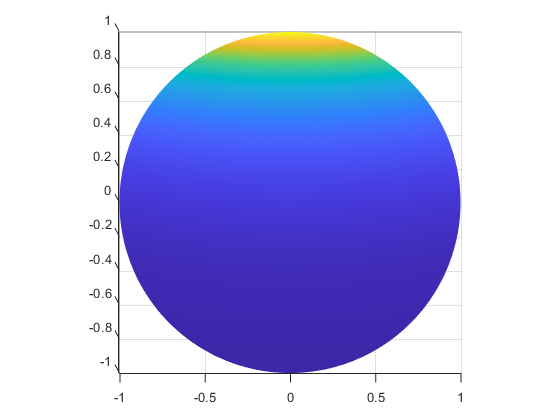

i=131;
j=241;
u=spherefun.coeffs2spherefun(transpose(reshape(f(:,i,j),m,n)));

% contour(phi/pi,theta/pi,u(phi,theta),[0:0.02:1]);axis equal;
plot(u);
view([0.17 -0.32])

% title(['x=' num2str(x(i)) '  z=' num2str(z(j))])
